**Параметры системы**

A1 = [1, 2, 0;
    0, 1, 3;
    1, -5, 1];
A2 = [0, 2, 0, 0;
    -2, 0, 0, 0;
    0, 0, 0, 1;
    0, 0, -1, 0];
B1 = [0; 2; 2];
B2 = [1, 0, 0, 0;
    0, 4, 0, 0;
    0, 0, 8, 0];

C1 = [0, 1, 0];
C2 = [1, 1, 1];
D1 = [1,2,3,4];
D2 = [5,6,7,8];

x0 = [1; 2; 3];
x1 = [-10; -15; 8];
w0 = [0; -2; -3; 1];
w1 = [-6;10;5;-4];

**Вычисление LQR регулятора**

Матрицы Q и R 

Q = eye(3);
R = 1;

Вычисление матрицы регулятора K1 LQR регулятор

[P, ~, ~] = icare(A1, B1, Q, R, [], [], [], []);
K1 = -inv(R) * B1' * P

K1 =    -5.2013   -3.0678   -1.3310


Вычисление матрицы K2 регулятора

cvx_begin sdp quiet;
variables P(length(A1),length(A2)) Y(1,length(A2))
P*A2 - A1*P == B1*Y + B2
C2*P + D2 == 0;
cvx_end;
K2 = Y - K1*P

K2 =    12.8830    4.1095    6.0173  -21.7188


Проверка системы на соответствие условий (принадлежности собств чисел А1 не в  С_, А2 к С+б A1+BK в С_)

% disp(eig(A1 + B1*K1));
eig([A1+B1*K1+L1*C1 B1*K2+B2+L1*D1; L2*C1 A2+L2*D1])

ans =  -45.8012 + 0.0000i
  28.6977 + 0.0000i
  -1.9993 + 0.0000i
   0.0174 + 1.9519i
   0.0174 - 1.9519i
  -0.0050 + 0.9161i
  -0.0050 - 0.9161i


Наблюдатель

Q = eye(7);
R = 1;
Z = zeros(4,3);
AF = [A1, B2;
    Z, A2];
CF = [C1, D1];
eig(AF);

M = -CF'*inv(R)*CF;

[P,K5,L5] = icare(AF',[],Q,[],[],[],M);

L = -P*CF'*inv(R);
L1 = L(1:3)

L1 =  -118.5055
  -18.1853
  -15.3737


L2 = L(4:7)

L2 =     1.2939
    0.5709
    1.3565
   -0.4000


Построение Графиков

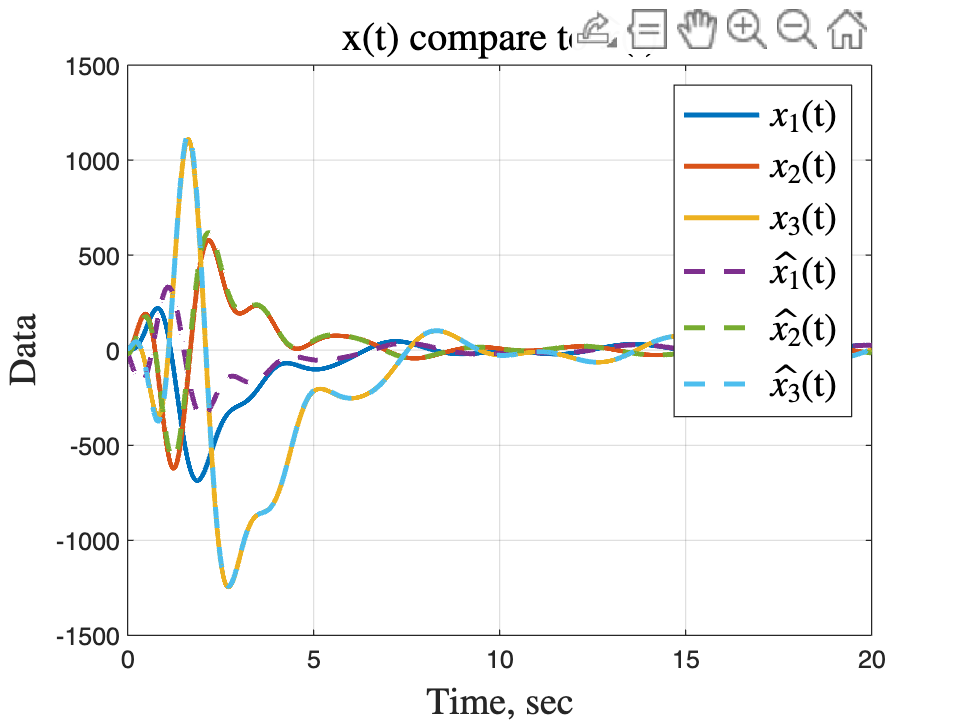

plot(out.x.Time, out.x.Data, 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data, 'LineWidth', 2, 'LineStyle','--');
title('x(t) compare to $\hat{x}$(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$x_{2}$(t)", "$x_{3}$(t)", "$\hat{x_{1}}$(t)","$\hat{x_{2}}$(t)","$\hat{x_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

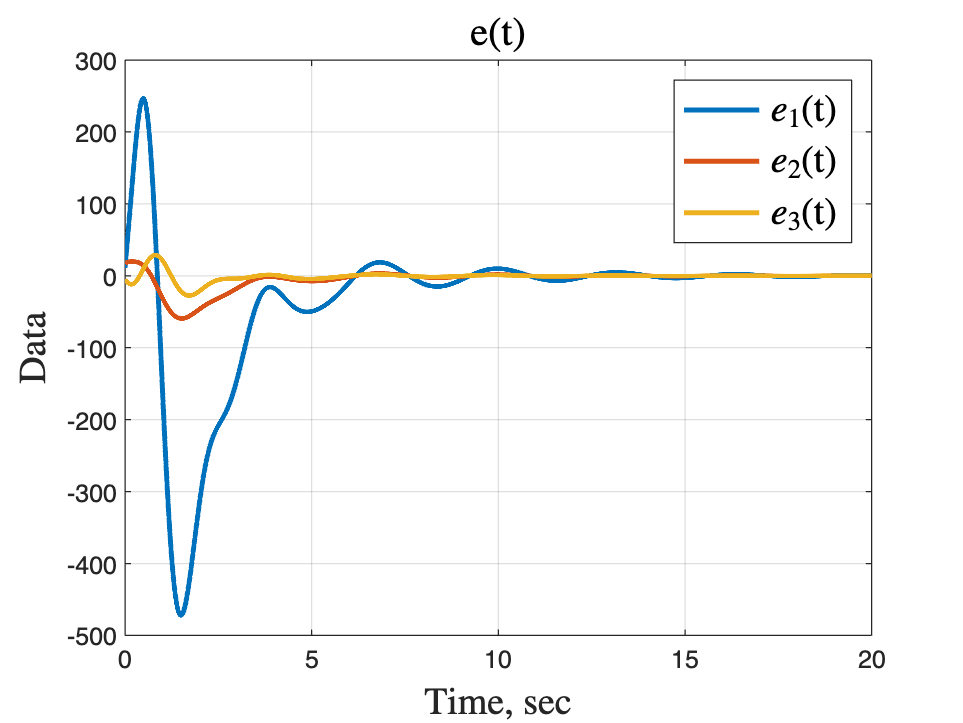


plot(out.e.Time, out.e.Data, 'LineWidth', 2);
title('e(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{1}$(t)","$e_{2}$(t)", "$e_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

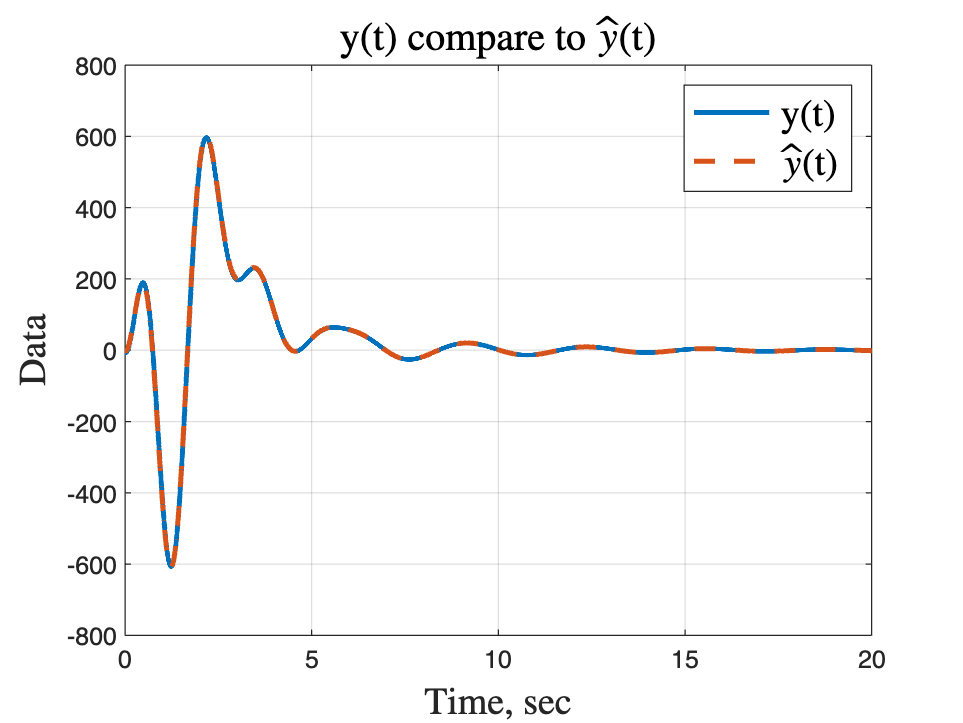


plot(out.y.Time, out.y.Data, 'LineWidth', 2);
hold on;
plot(out.yy.Time,out.yy.Data, 'LineWidth', 2, 'LineStyle','--');
title('y(t) compare to $\hat{y}$(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("y(t)","$\hat{y}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

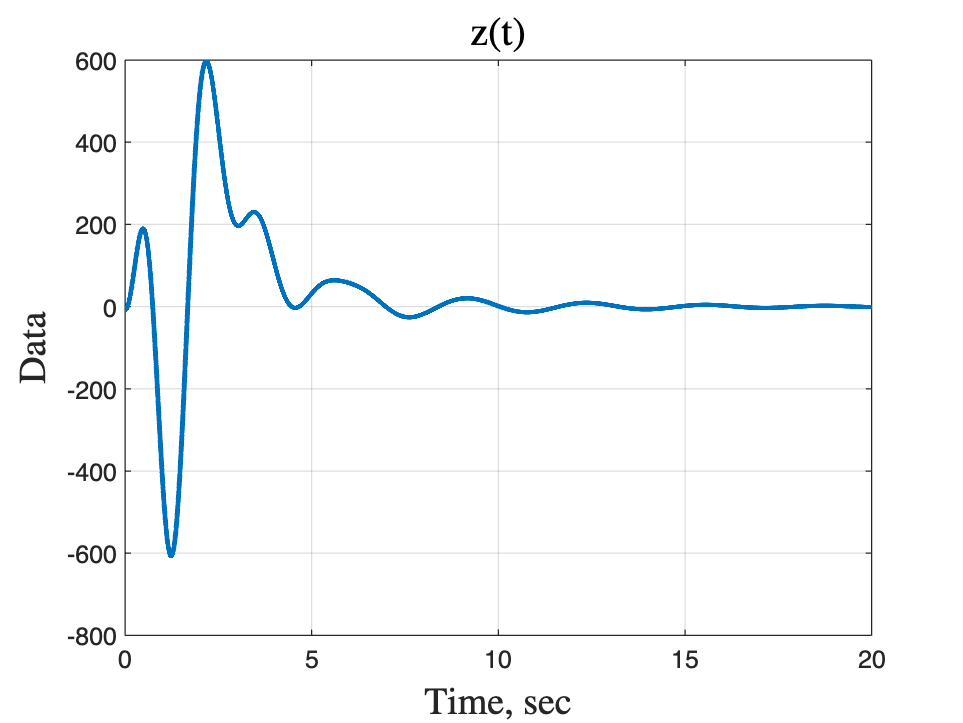


plot(out.z.Time, out.z.Data, 'LineWidth', 2);
hold on;
title('z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;